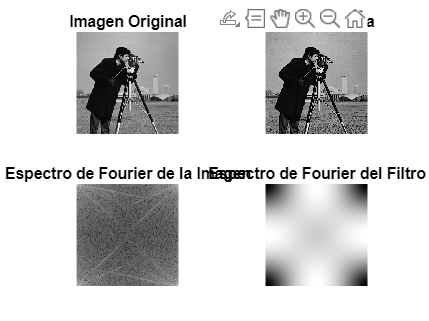

% Cargar la imagen
I = imread('cameraman.tif');

% Crear el filtro
h = fspecial('laplacian', 0.5);

% Aplicar la convolución en el dominio espacial
I_filtered = imfilter(I, h, 'conv', 'circular');

% Calcular la transformada de Fourier de la imagen y el filtro
G = fft2(I);
H = fft2(h, size(I,1), size(I,2));

% Multiplicar las transformadas y calcular la inversa
Y = (1/(size(I,1)*size(I,2))) * G .* H;
y = real(ifft2(Y));

% Mostrar los resultados
subplot(2,2,1), imshow(I), title('Imagen Original');
subplot(2,2,2), imshow(I-I_filtered), title('Imagen Filtrada');
subplot(2,2,3), imshow(log(1+abs(G)),[]), title('Espectro de Fourier de la Imagen');
subplot(2,2,4), imshow(log(1+abs(H)),[]), title('Espectro de Fourier del Filtro');